We'll examine the guessing/IVP approach for the case $\lambda=0.6$. 

lambda = 0.6;
phi = @(r,w,dwdr) lambda./w.^2 - dwdr./r;

We have to avoid $r=0$, or we would divide by zero.

a = eps;  b = 1;

We convert the ODE to a first-order system in $v_1$, $v_2$. 

f = @(r,v) [ v(2); phi(r,v(1),v(2)) ];

Now we try multiple guesses for the unknown $w(0)$ and plot the solutions. 

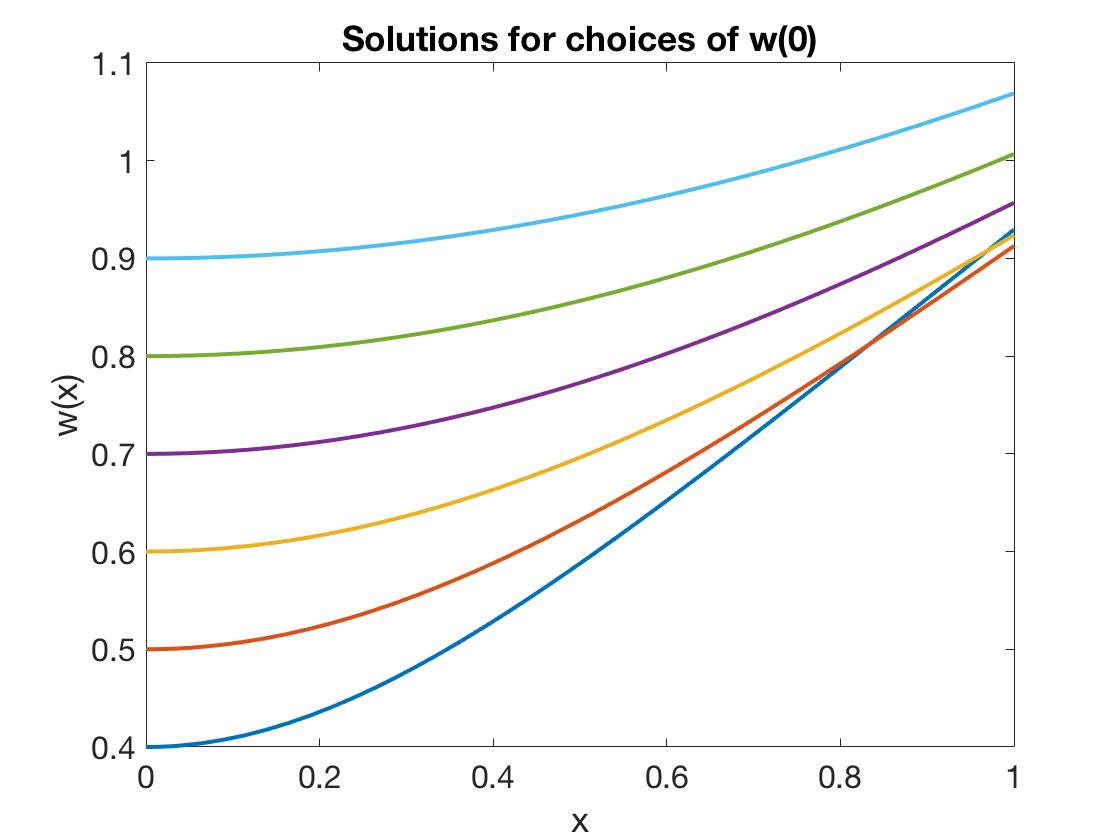

for w0 = 0.4:0.1:0.9
    [r,v] = ode45( f, [a,b], [w0;0] );
    plot(r,v(:,1)), hold on
end
xlabel('x'), ylabel('w(x)')    % ignore this line
title('Solutions for choices of w(0)')   % ignore this line

On the graph, it's the curve starting at $w(0)=0.8$ that comes closest to the required condition $w(1)=1$. 